# Trabajo práctico: Filtrado digital IIR

## 4) Diseño de un filtro IIR

### Diseñe un filtro digital tipo IIR a partir del diseño de un filtro analógico.

### a) Diseñe un filtro Chebyshev Tipo I pasa-banda entre 300 y 3.400 Hz con 3 dB en la banda pasante. Use las funciones cheb1ap() y lp2bp().

f1_c = 300; f2_c = 3400;    % Frecuencias de corte
[Z, P, K] = cheb1ap(10, 3); % Chebyshev Tipo 1 pasa bajo de orden 10, 3 dB de riple en banda pasante
[B, A] = zp2tf(Z, P, K);    % Forma de ceros y polos a función de transferencia
W1_c = 2*pi*f1_c; W2_c = 2*pi*f2_c;
Bw = W2_c - W1_c;           % Ancho de banda
Wo = sqrt(W1_c*W2_c);       % Frecuencia de centro
[B, A] = lp2bp(B, A, Wo, Bw);   % Conversión filtro pasa bajo a pasa banda

### b) Grafique la respuesta en frecuencia y fase del filtro analógico. Use la función freqs().

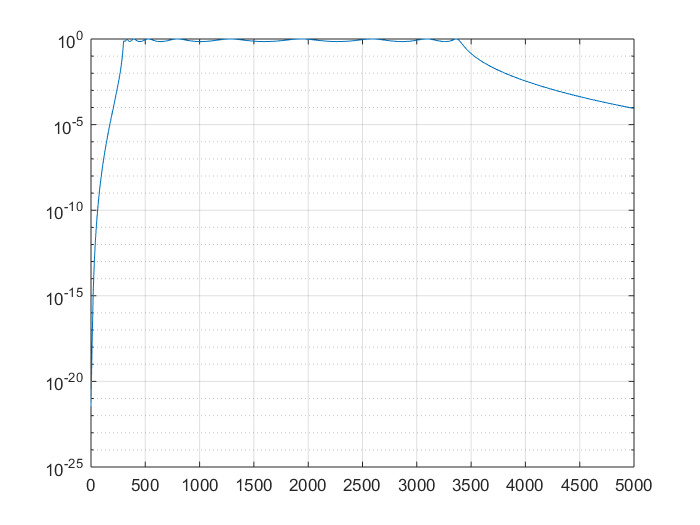

W = linspace(0, 10e3*pi, 500);
H_analog = freqs(B, A, W);
semilogy(W/2/pi, abs(H_analog));
grid on;

### c) Discretice el filtro analógico para una frecuencia de muestreo de 9600 Hz. Pruebe con los métodos de interpolación zoh, foh y tustin. Use la función c2d().

Fs = 9600;  % Frecuencia de muestreo
Ts = 1/Fs;   % Período de muestreo

[Z, P, K] = cheb1ap(10, 3);
[B, A] = zp2tf(Z, P, K);
W1_c = 2*pi*f1_c; W2_c = 2*pi*f2_c;
Bw = W2_c - W1_c;
Wo = sqrt(W1_c*W2_c);
[B, A] = lp2bp(B, A, Wo, Bw);
sysc = tf(B, A);    % Función de transferencia filtro analógico con prewarp
sysd = c2d(sysc, Ts, 'tustin');
[B, A] = tfdata(sysd, 'v');
[H_dig, ~] = freqz(B, A, 500, Fs);

Realizando un prewarp dado por la siguiente ecuación:


$$\Omega = \frac{2}{T} \tan(\omega / 2)$$


[Z, P, K] = cheb1ap(10, 3);
[B, A] = zp2tf(Z, P, K);
w1_c = 2*pi*f1_c/Fs; w2_c = 2*pi*f2_c/Fs; % Frecuencia discreta normalizada
W1_pw = (2/Ts)*tan(w1_c/2); W2_pw = (2/Ts)*tan(w2_c/2);
Bw = W2_pw - W1_pw;
Wo = sqrt(W1_pw*W2_pw);
[B, A] = lp2bp(B, A, Wo, Bw);
sysc = tf(B, A);    % Función de transferencia filtro analógico con prewarp
%[sysd, G] = c2d(sysc, Ts, 'tustin');
sysd = c2d(sysc, Ts, 'tustin');
[B, A] = tfdata(sysd, 'v');
[H_pw, F] = freqz(B, A, 500, Fs);

### d) Grafigue la respuesta en frecuencia y fase del filtro digital. Use la función freqz().

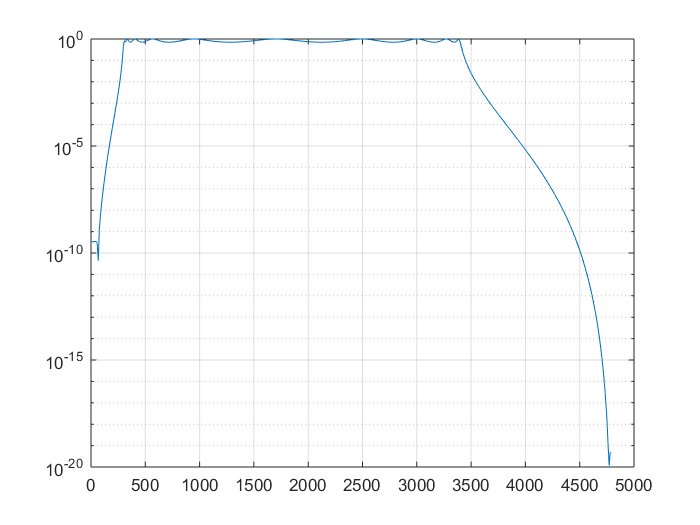

semilogy(F, abs(H_pw));
grid on;

### e) Compare con la respuesta de ambos filtros.

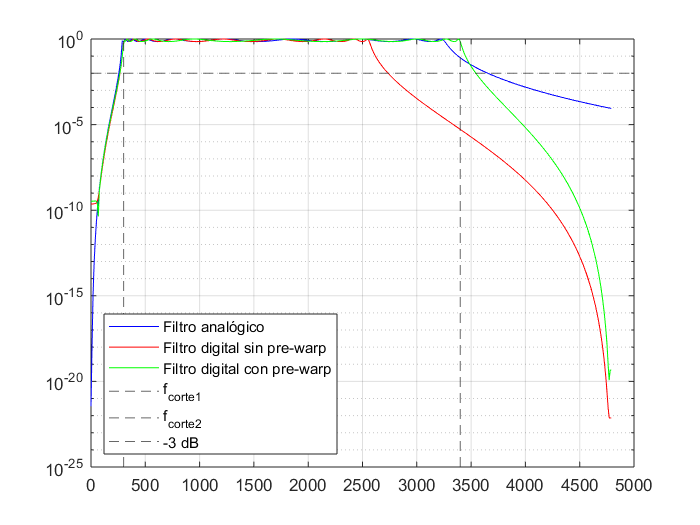

semilogy(F, abs(H_analog), '-b');
hold on;
semilogy(F, abs(H_dig), '-r');
semilogy(F, abs(H_pw), '-g');
grid on;
xline(f1_c, '--'); xline(f2_c, '--');
yline(10e-3, '--');
legend("Filtro analógico", "Filtro digital sin pre-warp", ...
    "Filtro digital con pre-warp", "f_{corte1}", "f_{corte2}", "-3 dB", ...
    'Location', 'southwest');
hold off;